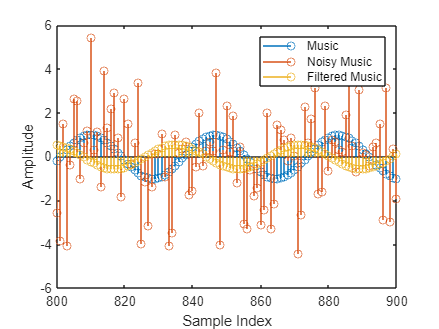

fs = 8000; % Sampling frequency
t = 0:1/fs:1; % Time vector from 0 to 1 second with sampling rate 8000 Hz
f = sin(2*pi*174.61*t);
g = sin(2*pi*195.99*t);
a = sin(2*pi*220*t);
b = sin(2*pi*246.94*t);
line1 = [a, b, g, f, f, b, b];
line2 = [a, b, b, f, f, g, g];
music = [line1, line2];

noise = 2*randn(size(music)); % Generate noise with the same size as music
noisy_music = music + noise; % Add noise to the music signal

cutoff = 200/(fs/2); % Cutoff frequency of 200Hz
order = 50; % Filter order

d = designfilt('highpassfir','CutoffFrequency',cutoff,'FilterOrder',order); % Design the high-pass filter

output = filter(d,music); % Apply the filter to the music signal

sound(output, fs) % Play the filtered music signal

figure
stem(music)
xlim([800 900])
hold on
stem(noisy_music)
xlim([800 900])
hold on
stem(output)
xlim([800 900])

xlabel('Sample Index') % Add x-axis label
ylabel('Amplitude') % Add y-axis label

legend('Music', 'Noisy Music','Filtered Music') % Add legend